# Plot Bilinear Lagrange Polynomials in Physical Space

Generates three graphs concerning a two-dimensional bilinear mesh in a tiled format: The two-dimensional basis functions, the provided parametric location mapped onto the physical space and the distribution of the geometric Jacobian in the parametric space of the provided element.

function t = plot2dBilinearLagrangePolynomialsOnPhysicalSpace ...
    (el, msh, numVertices, l1L1, l2L1, ij)

## **Function description**

Displays the bilinear basis functions on the two-dimensional bilinear quadrilateral mesh in the physical space.

**               Input :**

                    `el` : The element for which the parametric location is sought to be displayed in the physical space

                  `msh` : The one-dimensional bilinear mesh using four-noded elements as a structure with the following fields:

                              .`nodes` : Number of nodes in the one-dimensional mesh

                        .`elements` : Number of elements in the one-dimensional mesh

  `numVertices` : Number of vertices in the bilinear quadratic mesh

  `l1_L1`, `l2_L1` : The two Lagrange polynomials for the one-dimensional linear element

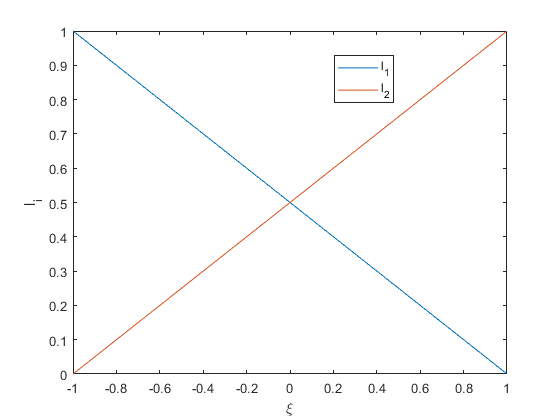

                    `ij` : Legend entries for the plot which should be an array with four elements

**          Output :**

                     `t` : Handle to the tiledlayout graphical object

## **Function Implementation**

### Input validation

    arguments
        el (1, 1) double {mustBeInteger, mustBeGreaterThanOrEqual(el, 1)}
        msh (1, 1) {mustHaveNodesAndElements}
        numVertices (1, 1) double {mustBeInteger, mustBePositive}
        l1L1 (1, 1) symfun
        l2L1 (1, 1) symfun
        ij (1, 4)
    end

### Read input

    syms l_Q1(x, y, x1, x2, y1, y2)

### Initialization of the tiled layout

    if floor(el) ~= el
        error("Variable 'el' should be an integer");
    end
    if el < 1 || el > numel(msh.elements(:, 1))
        error("Variable 'el' is chosen as %i but it should be an integer in the close interval [1, %i]", el, numel(msh.elements(:, 1)));
    end
    t = tiledlayout(2, 2);
    numNodes = numel(msh.elements(el, :));

### Nodes of the selected element in the quadrilateral patch

    Xel_Q1 =  msh.nodes(msh.elements(el, :), :);

### Loop over all the nodes in the quadrilateral patch

    for ii = 1:numNodes

#### Lagrange polynomial for the current node

        switch ii
            case 1
                idx1 = 1;
                idx2 = 4;
                idy1 = 1;
                idy2 = 2;
                l_Q1(x, y) = l1L1(x, Xel_Q1(idx1, 1), Xel_Q1(idx2, 1))*l1L1(y, Xel_Q1(idy1, 2), Xel_Q1(idy2, 2));
            case 2
                idx1 = 2;
                idx2 = 3;
                idy1 = 1;
                idy2 = 2;
                l_Q1(x, y) = l1L1(x, Xel_Q1(idx1, 1), Xel_Q1(idx2, 1))*l2L1(y, Xel_Q1(idy1, 2), Xel_Q1(idy2, 2));
            case 3
                idx1 = 2;
                idx2 = 3;
                idy1 = 4;
                idy2 = 3;
                l_Q1(x, y) = l2L1(x, Xel_Q1(idx1, 1), Xel_Q1(idx2, 1))*l2L1(y, Xel_Q1(idy1, 2), Xel_Q1(idy2, 2));
            case 4
                idx1 = 1;
                idx2 = 4;
                idy1 = 4;
                idy2 = 3;
                l_Q1(x, y) = l2L1(x, Xel_Q1(idx1, 1), Xel_Q1(idx2, 1))*l1L1(y, Xel_Q1(idy1, 2), Xel_Q1(idy2, 2));
            otherwise
                error("The bilinear quadrilateral should only have 4 nodes");
        end

#### graphical representation of the mesh along with the corresponding Lagrange polynomial associated to the current node

        nexttile
        plotMesh2d(msh, numVertices, true);
        hold on;
        fsurf(l_Q1(x, y), [min(Xel_Q1([idx1 idx2], 1)) max(Xel_Q1([idx1 idx2], 1)) min(Xel_Q1([idy1 idy2], 2)) max(Xel_Q1([idy1 idy2], 2))], ...
            "FaceColor",[217, 218, 219]./255, "FaceAlpha", 0.5);
        xlabel("x");
        ylabel("y");
        zlabel(sprintf("l_{%s}", num2str(ij(ii))))
        axis equal;
        hold off;
    end
    title(t, sprintf("Bilinear basis functions in the physical space of element %i", el));

end